# Bug 0

## Constants


% Wheel radious
wheel_r = 5.5/2; %cm

% Distance from center to wheel
l = (14.5/2 - 2.85/2);

% Perimeter of wheel
c = 2*pi*wheel_r; %cm

% Map Size
width = 100; %cm
height = 160; %cm
resolution = 1;

% Encoders ticks
tpr = [360 360];

% Differential tracktion, inverse problem
diffControl = [1/wheel_r l/wheel_r; 1/wheel_r -l/wheel_r];

## Robot

% Initialization
myev3 = legoev3('usb')

Unrecognized function or variable 'legoev3'.

beep(myev3)

% Connect and reset motors
r_motor = motor(myev3,'B');
l_motor = motor(myev3,'C');

% Connect and reset gyro
gyro = gyroSensor(myev3, 4);
resetRotationAngle(gyro)

% Color sensor
color = colorSensor(myev3, 2);

% Ultrasound Sensor
us = sonicSensor(myev3, 1);

## Bug 0

i = 1;

% Start and goal
startPoint = [60 0 pi/2];
goal = [50 140 pi/2];

% Variables initialization
position = startPoint;
angleList = [0 0; 0 0];
newAngSpeed = [0;0];

% Reset encoders
resetRotation(r_motor);
resetRotation(l_motor);

% Reset gyro
resetRotationAngle(gyro);

% Sampling Time
ts = 0.1;

% Distance to detect an object with ultrasound
distanceTreshold = 10 /100;

% Linear Speed
vel = 10;

% Initial State
state = 'go-to-goal';

% Distance to te goal
distanceToGoal = norm(position(1:2) - goal(1:2));

% Wheel Speed PID variables
speed_r = 0; speed_l = 0;

% Sensor data for plotting
usData = [0];
colorData = [0];
gyroData = [0];

goals = goal;

% Bug 0
while distanceToGoal>5
    % Time measurement
    tic
    
    % Read Sensors
    % Get wheels rotation
    
    rotation_r = -readRotation(r_motor);
    rotation_l = -readRotation(l_motor);
    angleList(i+1,:) = [rotation_r rotation_l];
    
    % US distance
    measureUs = readDistance(us);
    usData(i+1) = measureUs;

    % Color intensity
    measureIntensity = readLightIntensity(color, 'reflected');
    colorData(i+1) = measureIntensity;

    % Giro 
    measureGyro = deg2rad(-double(readRotationAngle(gyro))) + startPoint(3);
    gyroData(i+1) = measureGyro;

    % Get Wheels speed
    dr = (angleList(i+1,1)-angleList(i,1))/tpr(1)*c;
    dl = (angleList(i+1,2)-angleList(i,2))/tpr(2)*c;
    dteta = measureGyro-position(i, 3);
    d = double((dr+dl)/2);

    % Compute current position
    p = position(i,:)' + [d*cos(position(i,3));d*sin(position(i,3)); dteta];    

    % Bug 0 states
    switch state
        % No obstacles
        case 'go-to-goal'
            % Verify if US detects an object
            if measureUs <= distanceTreshold
                state = 'rotating';
            elseif measureIntensity > 0 
                state = 'avoid-obstacle';
            else
                % Else go to goal

                % Compute angle to goal
                omega = directionControl(p, goal);
                deltaPos = [vel;omega];
            end

        case 'rotating'      
            deltaPos = [0;2];
            
            % No obstacles, go to goal
            if measureIntensity > 0 
                state = 'avoid-obstacle';
            end

        case 'avoid-obstacle'
            % Detect if obstacle is in front or on the rigth side
            % Robot will try to stay parallel to object
            if measureIntensity > 0
                % No obstacle in front but in rigth, keep going forward
                deltaPos = [vel;0];
            end
            
            if measureIntensity > 20
                % if sensor is to close to wall
                deltaPos = [vel;0.5];
            end

            % No obstacles, go to goal
            if measureIntensity == 0 && measureUs > distanceTreshold
                state = 'repositioning';      
                newP = [p(1)+14*cos(p(3)) p(2)+14*sin(p(3)) p(3)];
                goals = [goals; newP];
            end

        case 'repositioning'
            % Detect if obstacle is in front or on the rigth side
            % Robot will try to stay parallel to object

             omega = directionControl(p, newP);
             deltaPos = [vel;omega];
            
            
            % No obstacles, go to goal
            if norm(position(i, 1:2) - newP(1:2)) < 5
                state = 'go-to-goal';
            end
    end
    
    % Compute new angular velocity for wheels
    newAngSpeed = diffControl * deltaPos;

    % PI Wheels speed controller
    [error_r, rotation_r, speed_r] = speedController(newAngSpeed(1), angleList(i,1), speed_r, r_motor, ts);
    [error_l, rotation_l, speed_l] = speedController(newAngSpeed(2), angleList(i,2), speed_l, l_motor, ts);

    % Append position to list for plot
    position(i+1, :) = p';

    % Compute distance to goal
    distanceToGoal = norm(position(i, 1:2) - goal(1:2));
    
    i=i+1;

    % Pause for sampling
    currentTime = toc;
    pause(ts-toc)
end
% Stop motors when reach goal
stop(r_motor)  
stop(l_motor)

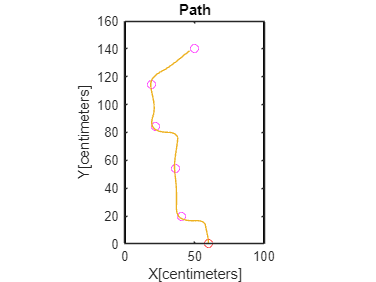

% plot path
figure
show(map, 'local')
title("Path")
hold on

plot(startPoint(1),startPoint(2),'ro')
plot(goals(:,1), goals(:,2),'mo')
plot(position(:, 1), position(:, 2))
ylabel("Y[centimeters]")
xlabel("X[centimeters]")
hold off

% Plot sensor data
figure
nexttile
plot(usData)
title("Ultrasound Data")
nexttile
plot(colorData)
title("Color Data")
nexttile
plot(gyroData)
title("Gyro Data")
nexttile

show(map, 'local')
title("Path")
hold on

plot(startPoint(1),startPoint(2),'ro')
plot(goals(:,1), goals(:,2),'mo')
plot(position(:, 1), position(:, 2))
hold off

% Save workspace
save('bug0ws')

## Functions

Direction control

function omega = directionControl(currentPos, goal)
    %% Direction Control
    direction = (goal' - currentPos) / norm(goal' - currentPos);

    % Orientation to goal
    desiredOrientation = atan2(direction(2), direction(1));

    % Error in orientation to goal
    orientationError = desiredOrientation - currentPos(3);
    
    % Map error in [-pi, pi]
    orientationError = atan2(sin(orientationError), cos(orientationError));
    
    % Compute new angular speed to face to goal
    Kp = 2; % Proportional gain
    omega = Kp * orientationError;
end


% Wheel speed control
function [error, rotation, speed] = speedController(rads, prevRotation, speed, motor, ts)
    % PID constants
    kp = 20;

    % Read rad/s
    rotation = -readRotation(motor);   

    rads_current = deg2rad((double(rotation) - double(prevRotation))/ts);
    rpmInrads = 17.802358370342162;
    
    % Compute error
    error = rads-rads_current;
    ErrorInSpeedP = error/rpmInrads;

    % Compute Speed
    speed = speed+kp*ErrorInSpeedP;

    % Saturation
    if speed > 100
        speed = 100;
    end
    if speed < -100
        speed = -100;
    end

    % Set Speed
    motor.Speed = -speed;

    start(motor);
end